clc, clearvars, close all

## Lab04: Generation, Processing, and Analysis of Sine Waves

## 1) Read Data

Load the provided signal 'signal.csv' using the 'csvread()' function and split the signal and time into two separate vectors.

fprintf('1) Start.\n')

1) Start.


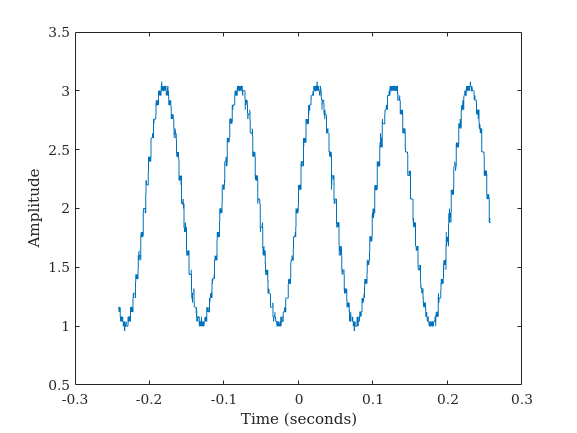


data = readmatrix("signal.csv", 'Range', 'D:E');

time = data(:, 1); 
signal = data(:, 2); 

% Plot the signal
figure(1)
plot(time, signal, 'DisplayName', 'Original Signal');
xlabel('Time (seconds)');
ylabel('Amplitude');


fprintf('1) Done.\n')

1) Done.


## 2/3) Butterworth Filter

Design a Butterworth filter that fulfills the required characteristics given in the assignment description. Use the built-in functions of Matlab. The 'doc' and 'help' functions might be useful to obtain detailed information.

% 2) First, calculate the required filter order and cutoff frequency and
% print the result.

fprintf('2) Start.\n')

2) Start.



difference= data(2,1)-data(1,1);
f_s = 1/difference; 
f_n = f_s / 2; 


fprintf('2) Done.\n')

2) Done.



% 3) Calculate the filter coefficients and apply them to the signal, i.e.,
% filter the signal. Plot the filtered signal into the same figure as the
% original signal. Make sure to add a title, the axis descriptions, and a
% legend.

fprintf('3) Start.\n')

3) Start.



Wp = 30 / f_n; 
Ws = 200 / f_n;
Rp = 3; 
Rs = 40; 

[n, Wn] = buttord(Wp, Ws, Rp, Rs);
[b, a] = butter(n, Wn);
filtered_signal = filter(b, a, signal);
fil2 = filter(b, a, filtered_signal)

fil2 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


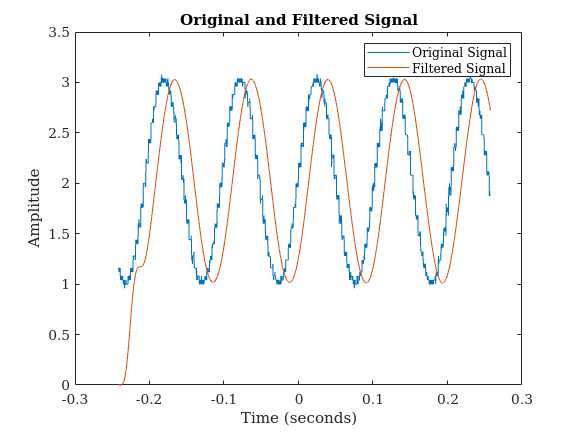

hold on;
plot(time, fil2, 'DisplayName', 'Filtered Signal');
hold off; 
title('Original and Filtered Signal');
legend('show'); 



fprintf('3) Done.\n')

3) Done.


## 4. Fourier Transform

Calculate the single-sided Fourier transform of the filtered signal.

fprintf('4) Start.\n')

4) Start.



% 4.1) First, obtain the length of the original and filtered signal and
% calculate their means. Print both mean values.

length_original = length(signal);
length_filtered = length(filtered_signal);

mean_original = mean(signal);
mean_filtered = mean(filtered_signal);

fprintf('Mean of Original Signal: %f\n', mean_original);

Mean of Original Signal: 2.032048


fprintf('Mean of Filtered Signal: %f\n', mean_filtered);

Mean of Filtered Signal: 2.001183


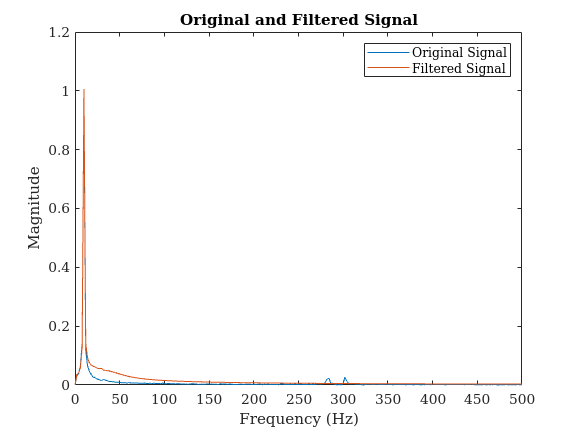





% 4.2) Do the FFT for both signals; see the docs and lecture slides for
% help. Make sure to remove the mean from the signals.

% 4.2.1.) Original signal

signal = signal - mean(signal);
f_signal = fft(signal);
n = length(signal);

P2 = abs(f_signal/n); 
P1 = P2(1:n/2+1); 
P1(2:end-1) = 2*P1(2:end-1); 
f = f_s*(0:(n/2))/n;

% 4.2.2) Filtered signal

filtered_signal = filtered_signal - mean(filtered_signal);
f_filtered_signal = fft(filtered_signal);
n_filtered = length(filtered_signal);


P2_filtered = abs(f_filtered_signal/n_filtered);
P1_filtered = P2_filtered(1:n_filtered/2+1);
P1_filtered(2:end-1) = 2*P1_filtered(2:end-1);
f_filtered = f_s*(0:(n_filtered/2))/n_filtered;


% 4.2.3) When plotting, only visualize the spectrum of to 500 Hz.


figure(2)

plot(f, P1,'DisplayName', 'Original Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 500]); 
hold on;
plot(f_filtered, P1_filtered,'DisplayName', 'Filtered Signal');
hold off;
title('Original and Filtered Signal');
legend('show'); 



fprintf('4) Done.\n')

4) Done.


## 5. Frequency Identification

Write a function that automatically detects a signals frequency based on its frequency spectrum. You can assume there's only a single signal and noise has been removed. The function must return the amplitude and the frequency of this signal.

fprintf('5) Start.\n')

5) Start.



% 5.2) What is the frequency of they signal you have analyzed?

[amplitude, frequency] = detectSignalFrequency(signal, f_s);

fprintf('Detected frequency: %f Hz\n', frequency);

Detected frequency: 10.000000 Hz


fprintf('Amplitude at this frequency: %f\n', amplitude);

Amplitude at this frequency: 0.986576




fprintf('5) Done.\n')

5) Done.



% 5.1) Define function


function [amplitude, frequency] = detectSignalFrequency(signal, f_s)


    n = length(signal);

    f_signal = fft(signal);

    P2 = abs(f_signal / n);

    P1 = P2(1:n/2+1);
    P1(2:end-1) = 2 * P1(2:end-1);

    f = f_s * (0:(n/2)) / n;

    [amplitude, idx] = max(P1);
    frequency = f(idx);
end
